% This script demonstrates the use of various point clouds - Section 4.1
load_javaplex;
clc; clear; close all;
import edu.stanford.math.plex4.*;

## Torus Example

% create the set of points
point_cloud = examples.PointCloudExamples.getRandomTorusPoints(2000, 1, 2);

figure

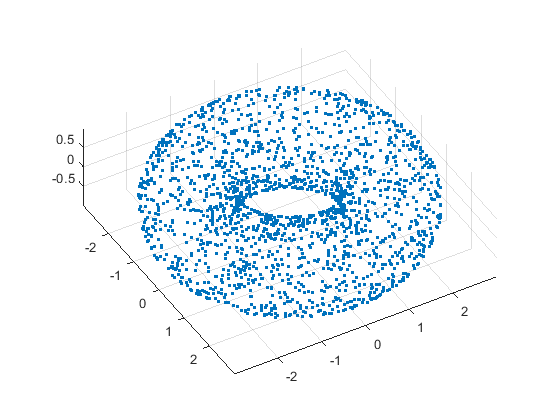

scatter3(point_cloud(:,1), point_cloud(:,2), point_cloud(:,3), '.')
axis equal
view(60,40)

## Sphere Example

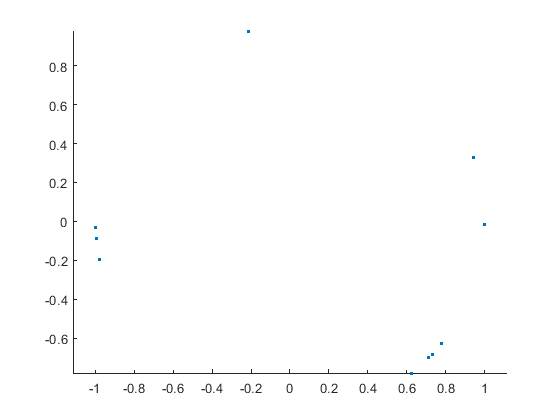

% create the set of points
% The following gets 1000 points on the torus S^1 x S^1 in R^4
% One can use the same to get uniformly random points on S^k x ... x S^k
% (any finite product of k-spheres)
point_cloud = examples.PointCloudExamples.getRandomSphereProductPoints(10, 1, 2);

figure
scatter(point_cloud(:,3), point_cloud(:,4), '.')
axis equal


max_dimension = 4;
max_filtration_value = 4;
num_divisions = 10;
% create a Vietoris-Rips stream 
stream = api.Plex4.createVietorisRipsStream(point_cloud, max_dimension, max_filtration_value, num_divisions);
% get a new ExplicitSimplexStream
stream = api.Plex4.createExplicitSimplexStream();

% construct a triangle
stream.addVertex(0);
stream.addVertex(1);
stream.addVertex(2);
stream.addElement([0, 1]);
stream.addElement([0, 2]);
stream.addElement([1, 2]);

% print out the total number of simplices in the complex
size = stream.getSize()

size = 6

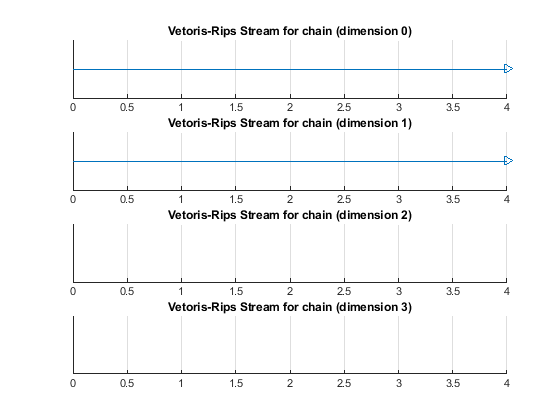

% get persistence algorithm over Z/pZ
p_field=19;
%persistence = api.Plex4.getModularSimplicialAlgorithm(max_dimension, p_field);
persistence = api.Plex4.getDefaultSimplicialAlgorithm(3);

% compute the intervals
intervals = persistence.computeIntervals(stream);

% create the barcode plots
options.filename = 'Vetoris-Rips Stream for chain';
options.max_filtration_value = max_filtration_value;
options.max_dimension = max_dimension - 1;
plot_barcodes(intervals, options);


%convert to cochain complex.

costream = streams.derived.DualStream(stream)


costream =

edu.stanford.math.plex4.streams.derived.DualStream@17410c07



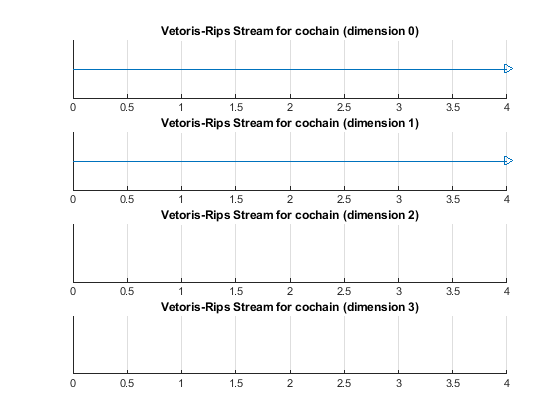

% costream.getMaximumFiltrationIndex()
% p_field=19;
%copersistence = api.Plex4.getModularSimplicialAlgorithm(max_dimension, p_field);
copersistence = api.Plex4.getDefaultSimplicialAlgorithm(3);
cointervals = copersistence.computeIntervals(costream);
options.filename = 'Vetoris-Rips Stream for cochain';
plot_barcodes(cointervals, options);


% We get the boundary matrix from the costream, cochain complex associated with the original chain complex.
% compute boundary
d_0 = streams.utility.StreamUtility.createBoundaryMatrixAsDoubleSum(costream, 0)


d_0 =

([1,2], [2]) + ([0,2], [2]) + ([0,1], [1]) + -([0,1], [0]) + -([1,2], [1]) + -([0,2], [0])



d_1 = streams.utility.StreamUtility.createBoundaryMatrixAsDoubleSum(costream, 1)


d_1 =






% convert from sparse form to array
converter = api.Plex4.createHomMatrixConverter(costream, costream);
d_0_array = converter.toArray(d_0);
d_1_array = converter.toArray(d_1);
% isequal(d_0_array,d_1_array)

%Nonlinear generic optimization functionality.
%z = fminsearch(@myfun,z0)
%We are handling with Fun(f-d_0_array%*%z),Fun can either be regularized
%norm or other function like elastic net of interest.
%Let's try L^2 norm first.
f = 1:3;

Undefined operator ':' for input arguments of type 'struct'.

uz0 = [2 1 3];
%coboundary matrix delta
delta = d_0_array(4:6,1:3);
%costfunc is L^2.
costfunc = @(x)transpose(transpose(f)-delta*transpose(x))*(transpose(f)-delta*transpose(x));
%options = optimoptions('fmincon','Display','iter');
z_min = fminsearch(costfunc,uz0);
%Show the minimum and the argmin.
z_min
costfunc(z_min)